load('DatosExperimentales.mat')
a1Val=0.1:0.005:0.3; % Valores de a1 y s
sVal=0:0.005:0.5;
N=length(TexpPRBS);
Ts=9;
v=[time uPRBS]; %Entrada
na1=length(a1Val);
ns=length(sVal);

V=zeros(na1,ns);

for i=1:na1 %Variación del parametro a1
    a1=a1Val(i);
    for j=1:ns %Variación del parametro s
        s=sVal(j);
        sim("modelo_bus_exh.slx")
        V(i,j)=sum((TexpPRBS-Test).^2)/N;
    end
end
Vopt=min(V,[],'all');
[Na1Opt, NsOpt]= find(V==Vopt);
a1=a1Val(Na1Opt);
s=sVal(NsOpt);
Opt=[a1 s];

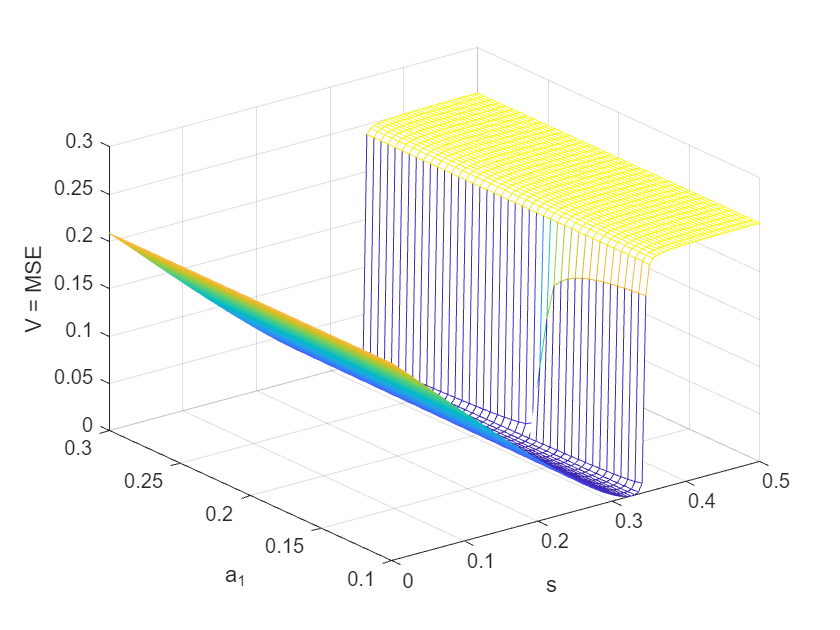

figure(1)
mesh(sVal,a1Val,V)
xlabel('s')
ylabel('a_{1}')
zlabel('V = MSE')

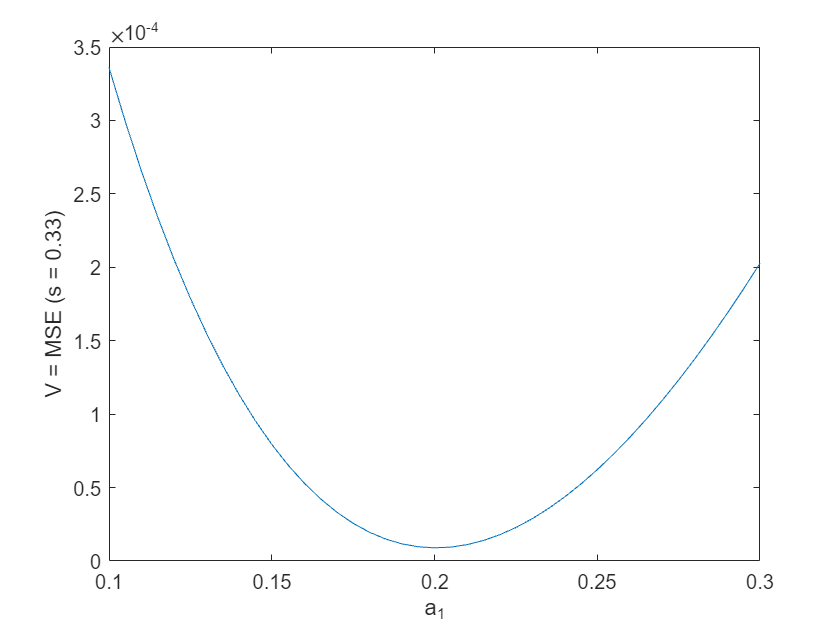


figure(2)
plot(a1Val, V(:,NsOpt))
xlabel('a_{1}')
ylabel("V = MSE (s = " + string(s) + ")")

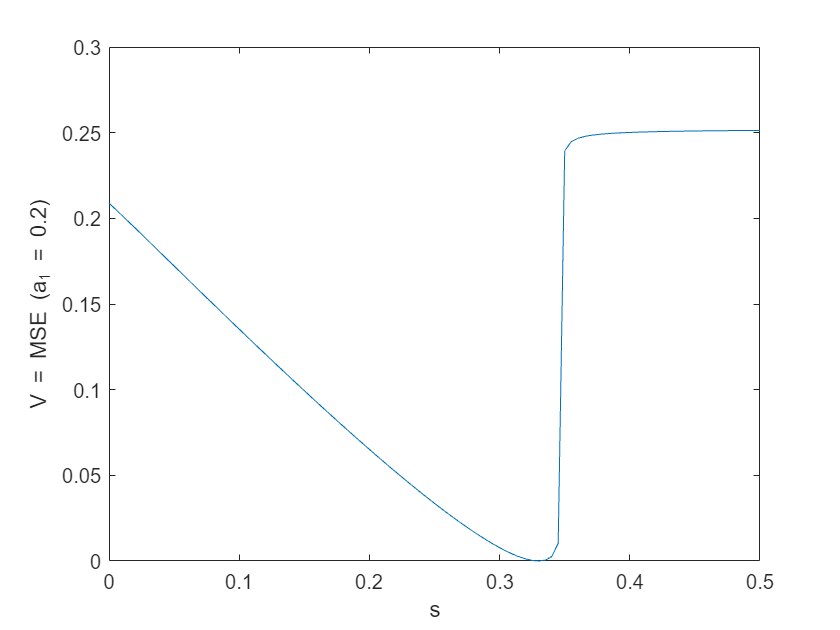


figure(3)
plot(sVal, V(Na1Opt,:))
xlabel('s')
ylabel("V = MSE (a_{1} = " + string(a1) + ")")

results=array2table([a1 s round(Vopt,3,'significant')],'VariableNames',["a_{1}", "s", "V"]);
disp(results)

    a_{1}     s         V    
    _____    ____    ________

     0.2     0.33    8.97e-06



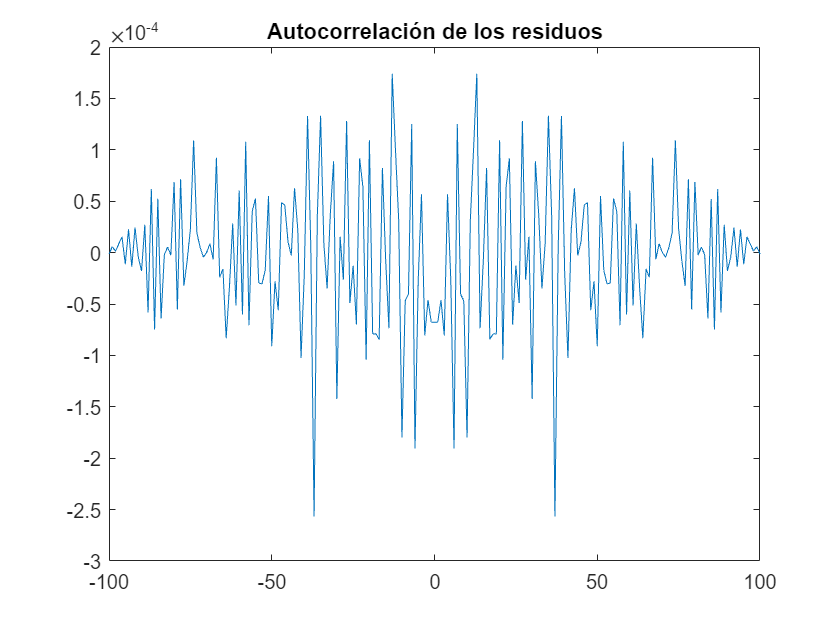

sim("modelo_bus_exh.slx")
e=TexpPRBS-Test;
[c, lags] = xcorr(e);
lags(101)=[];
c(101)=[];
plot(lags,c)
title("Autocorrelación de los residuos")